clear;
clc;

% symbolized parameters
syms theta_1 theta_2 delta_1 delta_2 pi L_1 L_2;
%L_1 = 50;
%L_2 = 50;

% transformation matrices for the first segment
for i = 1:3
    if i == 1
        alpha = 0; a = 0; d = 0; theta = delta_1;
        T1 = [cos(theta) -cos(alpha)*sin(theta) sin(alpha)*sin(theta) a*cos(theta);
              sin(theta) cos(alpha)*cos(theta) -sin(alpha)*cos(theta) a*sin(theta);
              0 sin(alpha) cos(alpha) d;
              0 0 0 1];
    elseif i == 2
        alpha = -pi/2; a = 0; d = 0.5*L_1; theta = -pi/2;
        T2 = [cos(theta) -cos(alpha)*sin(theta) sin(alpha)*sin(theta) a*cos(theta);
              sin(theta) cos(alpha)*cos(theta) -sin(alpha)*cos(theta) a*sin(theta);
              0 sin(alpha) cos(alpha) d;
              0 0 0 1];
    elseif i == 3
        alpha = pi/2; a = (L_1)/2; d = 0; theta = -(pi/2)-theta_1;
        T3 = [cos(theta) -cos(alpha)*sin(theta) sin(alpha)*sin(theta) a*cos(theta);
              sin(theta) cos(alpha)*cos(theta) -sin(alpha)*cos(theta) a*sin(theta);
              0 sin(alpha) cos(alpha) d;
              0 0 0 1];
        
    end
end
trans = T1*T2*T3;
disp(trans);

Rx = trans(1:3,1);
Ry = trans(1:3,2);
Rz = trans(1:3,3);
px1 = trans(1,4);
py1 = trans(2,4); 
pz1 = trans(3,4);
%disp(pz);
pose = transpose([px1 py1 pz1]);
disp(pose);

$$\begin{array}{l} \left(\begin{array}{c} \frac{L_{1}\,\sigma_{1}\,\left(\sigma_{2}\,\sin\left(\delta_{1}\right)-\cos\left(\frac{\pi }{2}\right)\,\sin\left(\frac{\pi }{2}\right)\,\cos\left(\delta_{1}\right)\right)}{2}+\frac{L_{1}\,\sigma_{3}\,\left(\cos\left(\frac{\pi }{2}\right)\,\cos\left(\delta_{1}\right)+\sin\left(\frac{\pi }{2}\right)\,\sin\left(\delta_{1}\right)\right)}{2}\\ \frac{L_{1}\,\sigma_{3}\,\left(\cos\left(\frac{\pi }{2}\right)\,\sin\left(\delta_{1}\right)-\sin\left(\frac{\pi }{2}\right)\,\cos\left(\delta_{1}\right)\right)}{2}-\frac{L_{1}\,\sigma_{1}\,\left(\cos\left(\delta_{1}\right)\,\sigma_{2}+\sin\left(\frac{\pi }{2}\right)\,\sin\left(\delta_{1}\right)\,\cos\left(\frac{\pi }{2}\right)\right)}{2}\\ \frac{L_{1}}{2}+\frac{L_{1}\,\sigma_{1}\,\sin\left(\frac{\pi }{2}\right)}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{\pi }{2}+\theta_{1}\right)\\ \sigma_{2}={\cos\left(\frac{\pi }{2}\right)}^{2}\\ \sigma_{3}=\cos\left(\frac{\pi }{2}+\theta_{1}\right) \end{array}$$

clear;
k1 = 1;
config1 = [];
cartesian1 = [];
% config = gpuArray([]);
% cartesian = gpuArray([]);

while k1 <= 10000
    
    delta_1 = deg2rad(359).*rand();
    theta_1 = deg2rad(89).*rand();
    delta_2 = deg2rad(360).*rand();
    theta_2 = deg2rad(90).*rand();
    
    px1(k1) = (50*sin(delta_1)*cos(theta_1 + pi/2))/2;
    py1(k1) = -(50*cos(delta_1)*cos(theta_1 + pi/2))/2;
    pz1(k1) = 25 + (50*sin(theta_1 + pi/2))/2;
    
    dir_alpha_Rx1(k1) = sin(delta_1)*cos(theta_1 + pi/2);
    dir_beta_Rx1(k1) = -cos(delta_1)*cos(theta_1 + pi/2);
    dir_gamma_Rx1(k1) = sin(theta_1 + pi/2);
    dir_alpha_Ry1(k1) = cos(delta_1);
    dir_beta_Ry1(k1) =  sin(delta_1);
    dir_gamma_Ry1(k1) =  0;
    dir_alpha_Rz1(k1) = -sin(delta_1)*sin(theta_1 + pi/2);
    dir_beta_Rz1(k1) = cos(delta_1)*sin(theta_1 + pi/2);
    dir_gamma_Rz1(k1) = cos(theta_1 + pi/2);
    
    % covert rotation matrices to euler angles
    rot1 = [dir_alpha_Rx1(end,end) dir_alpha_Ry1(end,end) dir_alpha_Rz1(end,end);
           dir_beta_Rx1(end,end) dir_beta_Ry1(end,end) dir_beta_Rz1(end,end);
           dir_gamma_Rx1(end,end) dir_gamma_Ry1(end,end) dir_gamma_Rz1(end,end)];
    
    append_eul1 = rotm2eul(rot1);
    % data preparation for the neural network
    

    append_cartesian = [px1(k1) py1(k1) pz1(k1)];
    cartesian1 = [cartesian1; append_cartesian append_eul1];
    k1 = k1+1;
end

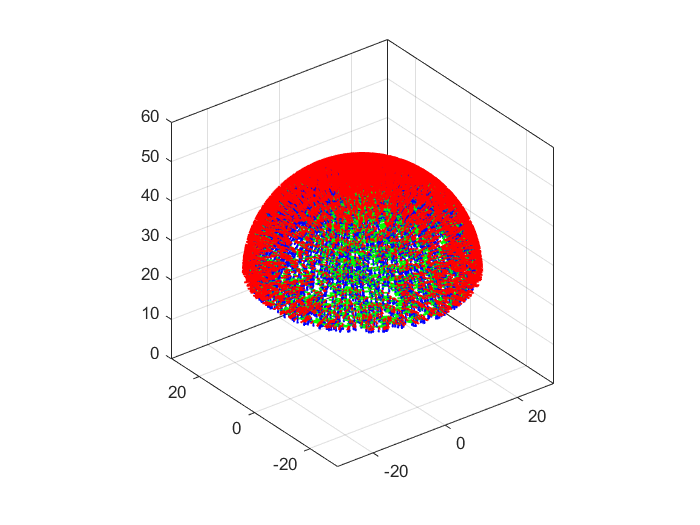

% plot workspace in jet color


% plot orientation of the proximal segment
figure;
hx1 = quiver3(px1,py1,pz1,dir_alpha_Rx1,dir_beta_Rx1,dir_gamma_Rx1,'r','LineWidth',1,'AutoScaleFactor',2);
hold on;
hy1 = quiver3(px1,py1,pz1,dir_alpha_Ry1,dir_beta_Ry1,dir_gamma_Ry1,'g','LineWidth',1,'AutoScaleFactor',2);
hold on;
hz1 = quiver3(px1,py1,pz1,dir_alpha_Rz1,dir_beta_Rz1,dir_gamma_Rz1,'b','LineWidth',1,'AutoScaleFactor',2);
hold on;
axis equal
axis ([-30 30 -30 30 0 60]);

%view([0.0 0.0]);
box on;
grid on;